## Homework 4

Erivelton Gualter dos Santos

# 1: LQR design with linearized plant

- Governing equation for magnetic levitation system:


$$\ddot{x} + \frac{ki^2}{2x^2} -mg = 0$$


- Show equilibrium point:

Considering states variables as $[x_1 \  x_2]^T = [x \ \dot{x}]^T$, than we have the followign state space representation:


$$\dot{x}_1 = x_2 \\
\dot{x}_2 = -\frac{ki^2}{2x_1^2}-mg$$


In order to find the equilibrium points, we have $\dot{x}_1 = \dot{x}_2 = 0$, then :


$$-\frac{ki^2}{2x^2}-mg =0 \\
i_{eq}  = \sqrt{\frac{2x_{eq}^2mg}{k}}$$


where $k_{ff}  = \sqrt{\frac{2mg}{k}}$.

- Lineazired differential equaltion model of $mg-F $ at equilibrium points: $i_{eq} $ and $x_{eq}
$:


$$mg-F\simeq  (mg - F) |_{x_{eq} ,i_{eq}}+ \frac{ki^2}{x^3} |_{x_{eq} ,i_{eq}}(x-x_{eq})-\frac{ki}{x^2} |_{x_{eq} ,i_{eq}}(i-i_{eq})$$


syms x xeq i ieq k m g kff

% ieq = kff*xeq;
% ieq = sqrt(2*m*g/k)*xeq;

F = k*ieq^2*(x-xeq)/xeq^3 - k*ieq*(i-ieq)/xeq^2;
pretty(simplify(F))

  ieq k (i xeq - ieq x)
- ---------------------
              3
           xeq





% Simulation
m = 0.068;          % Mass of the ball, kg
k = 6.5308*1e-5;    % Nm^2/A^2
g = 9.81;           % Acceleration of gravity, m/s^2
param = [m; k; g];

kff = sqrt(2*m*g/k); 

% Equilibrium Point
xeq = 6e-3;
ieq = kff*xeq;

% Initial Condition
% X0 = [7e-3; 0 ];    % Step of 1mm
X0 = [14e-3; 0 ];
% X0 = [xeq+ 1e-3; 0];

% LQR Controller
% A = [0 1; k*ieq^2/xeq^3/m 0];
% B = [0; -k*ieq/xeq^2/m];
A = [0 1; 2*g/xeq 0];
B = [0; -2*g/ieq];

Q = diag([10 1]);
R = 1e-3;
K = lqr(A,B,Q,R)

K =  -317.3675  -32.0584


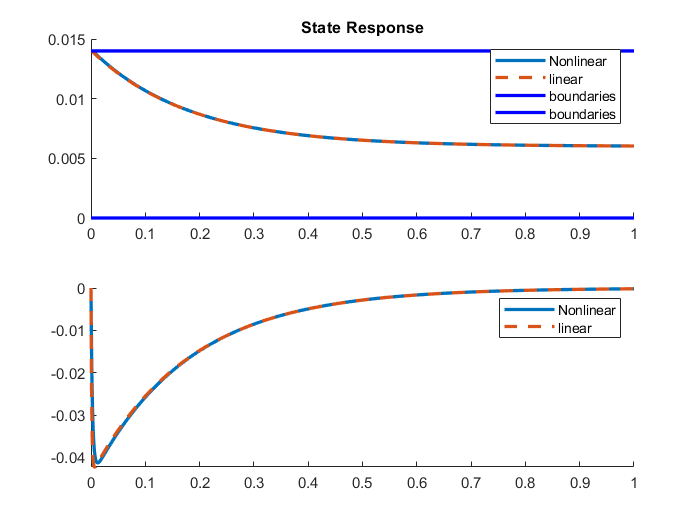


sim('maglev.slx',1);

figure('Name','Nonlinear and Linear State Response');
ax1 = subplot(211); hold on; plot(t, X(:,1), 'linewidth', 2); plot(t, X2(:,1), '--', 'linewidth', 2); title('State Response');
ax2 = subplot(212); hold on; plot(t, X(:,2), 'linewidth', 2); plot(t, X2(:,2), '--', 'linewidth', 2); 
legend('Nonlinear','linear');

% Plot boundaries
plot(ax1, t,zeros(size(t)), '-b', 'linewidth', 2); plot(ax1, t, 0.014*ones(size(t)), '-b', 'linewidth', 2)
legend(ax1, 'Nonlinear','linear','boundaries','boundaries');

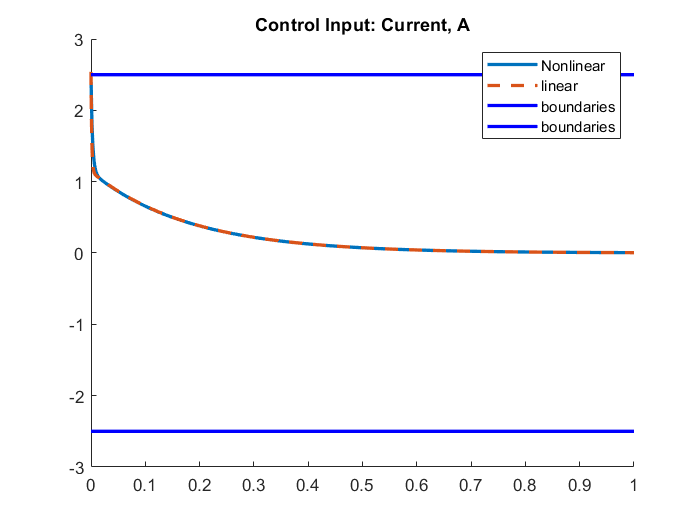


figure('Name','Control Input');
title('Control Input: Current, A');
hold on; plot(t, i, 'linewidth', 2); plot(t, deltai, '--', 'linewidth', 2); legend('Nonlinear','linear');

% Plot boundaries
plot(t,-2.5*ones(size(t)), '-b', 'linewidth', 2); plot(t, 2.5*ones(size(t)), '-b', 'linewidth', 2)
legend('Nonlinear','linear','boundaries','boundaries');

# Quadratic Lyapunov Function and Region of Attraction

Q = eye(2);
Acl = A-B*K;
P = lyap(Acl',Q);

syms x1 x2
V = 0.5*[(x1-xeq) x2]*P*[(x1-xeq); x2];
vpa(simplify(V), 4)

$$ans = \left(x_{1}-0.006\right)\,\left(1.407\,x_{1}+6.264\,10^{-5}\,x_{2}-0.00844\right)+x_{2}\,\left(6.264\,10^{-5}\,x_{1}+0.0003409\,x_{2}-3.759\,10^{-7}\right)$$

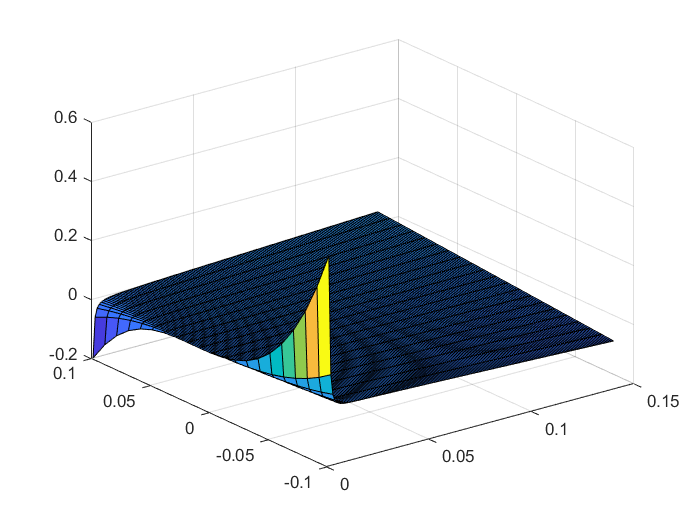


V_sym = matlabFunction(V, 'vars', [x1,x2]);

u = ieq - K*[x1-xeq; x2];
x1d = x2;
x2d = (m*g-k.*u^2/2/x1^2)/m;

Vdot = diff(V,x1)*x1d + diff(V,x2)*x2d;
Vdot_sym = matlabFunction(Vdot, 'vars', [x1,x2]);

% [x1, x2] = meshgrid(0:1e-4:.014, -.1:1e-2:.1);
[x1, x2] = meshgrid(0:1e-3:.14, -.1:1e-2:.1);
V = V_sym(x1, x2);
Vdot = Vdot_sym(x1, x2);

% figure('Name','Lyapunov Function'); title('Lyapunov Function');
% surf(x1,x2,V)
figure('Name','Lyapunov Function'); title('Der Lyapunov Function');
surf(x1,x2,Vdot);

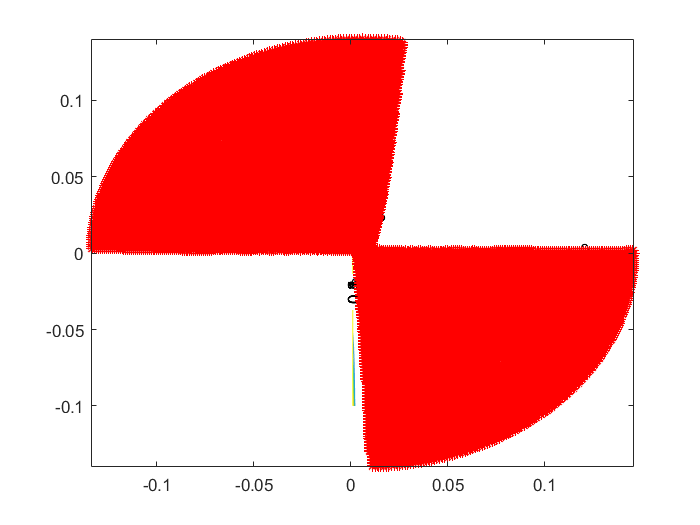

figure;
[c,h]=contour(x1,x2,Vdot);
clabel(c,h)
hold on;
P1 = [];
P2 = [];
for r = 0:1e-3:.14
    for th = 0:.01:2*pi,
        x1 = r*cos(th)+6e-3;
        x2 = r*sin(th);  %absolute coords
        vdot = Vdot_sym(x1,x2);
        if vdot > 0
            P1 = [P1 [x1;x2]];
        else
            P2 = [P2 [x1;x2]];
        end
    end
end
plot(P2(1,:),P2(2,:), 'r*');



% Vdot = ;
% quiver(x1,x2,x1dot, x2dot, 'color', 'cyan')